path1 = "D:\files\spectral_analysis\mat_demo\demo_pretreatment\ftnir\zd\";
csvs1 = dir(fullfile(path1, '*.csv'));
X_ftnir_zd = zeros(1557, 10);
for i = 1:10
    data_read = csvread(strcat(path1,csvs1(i).name));
    X_ftnir_zd(:,i) = data_read(:,2);
    
end

path2 = "D:\files\spectral_analysis\mat_demo\demo_pretreatment\ftnir\jd\";
csvs2 = dir(fullfile(path2, '*.csv'));
X_ftnir_jd = zeros(1557, 10);
for i = 1:10
    data_read = csvread(strcat(path2,csvs2(i).name));
    X_ftnir_jd(:,i) = data_read(:,2);
    
end

path3 = "D:\files\spectral_analysis\mat_demo\demo_pretreatment\ftnir\nh\";
csvs3 = dir(fullfile(path3, '*.csv'));
X_ftnir_nh = zeros(1557, 10);
for i = 1:10
    data_read = csvread(strcat(path3,csvs3(i).name));
    X_ftnir_nh(:,i) = data_read(:,2);
    
end

path4 = "D:\files\spectral_analysis\mat_demo\demo_pretreatment\ftnir\jh\";
csvs4 = dir(fullfile(path4, '*.csv'));
X_ftnir_jh = zeros(1557, 10);
for i = 1:10
    data_read = csvread(strcat(path4,csvs4(i).name));
    X_ftnir_jh(:,i) = data_read(:,2);
    
end

wavenumber = data_read(:,1);

## combine

X_ftnir = [X_ftnir_zd,X_ftnir_jd,X_ftnir_nh,X_ftnir_jh];
X_ftnir = X_ftnir.'

X_ftnir =     1.1878    1.1882    1.1883    1.1883    1.1880    1.1875    1.1866    1.1854    1.1836    1.1815    1.1796    1.1772    1.1745    1.1718    1.1693    1.1662    1.1631    1.1600    1.1568    1.1533    1.1497    1.1461    1.1428    1.1396    1.1364    1.1331    1.1301    1.1269    1.1237    1.1207    1.1177    1.1148    1.1122    1.1096    1.1071    1.1049    1.1029    1.1011    1.0995    1.0979    1.0968    1.0956    1.0945    1.0939    1.0934    1.0930    1.0927    1.0924    1.0921    1.0921
    1.2214    1.2227    1.2234    1.2233    1.2230    1.2225    1.2218    1.2205    1.2187    1.2168    1.2150    1.2128    1.2100    1.2074    1.2048    1.2017    1.1986    1.1954    1.1922    1.1886    1.1850    1.1815    1.1781    1.1748    1.1717    1.1685    1.1655    1.1624    1.1593    1.1563    1.1531    1.1501    1.1473    1.1448    1.1426    1.1405    1.1385    1.1367    1.1353    1.1340    1.1330    1.1321    1.1311    1.1303    1.1300    1.1298    1.1297    1.1295    1.129

y_ftnir = [ones(10,1);ones(10,1)*2;ones(10,1)*3;ones(10,1)*4];

X_ftnir_air = pre_airpls(X_ftnir, 10e3);

X_ftnir_air_sg = pre_sgfilter(X_ftnir_air, 15, 2, 0);

X_ftnir_air_sg_v = reshape(X_ftnir_air_sg, 1, size(X_ftnir_air_sg, 1)*size(X_ftnir_air_sg, 2));
X_ftnir_air_sg_01_v = mapminmax(X_ftnir_air_sg_v, 0, 1);
X_ftnir_air_sg_01 = reshape(X_ftnir_air_sg_01_v, size(X_ftnir_air_sg, 1), size(X_ftnir_air_sg, 2));

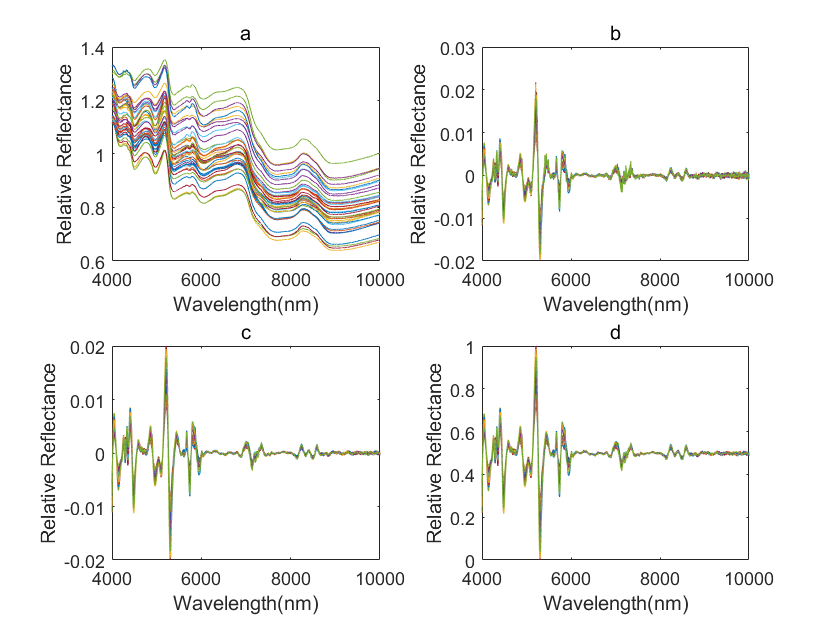

figure;
subplot(2,2,1);
for k = 1:size(X_ftnir, 1)
    plot(wavenumber, X_ftnir(k, :));
    hold on;
end 
xlim([4000, 10000])
xlabel('Wavenumber(cm^{-1})')
ylabel('Relative Reflectance')
title('a')

subplot(2,2,2);
for k = 1:size(X_ftnir, 1)
    plot(wavenumber, X_ftnir_air(k, :));
    hold on;
end 
xlim([4000, 10000])
xlabel('Wavenumber(cm^{-1})')
ylabel('Relative Reflectance')
title('b')

subplot(2,2,3);
for k = 1:size(X_ftnir, 1)
    plot(wavenumber, X_ftnir_air_sg(k, :));
    hold on;
end
xlim([4000, 10000])
xlabel('Wavenumber(cm^{-1})')
ylabel('Relative Reflectance')
title('c')

subplot(2,2,4);
for k = 1:size(X_ftnir, 1)
    plot(wavenumber, X_ftnir_air_sg_01(k, :));
    hold on;
end 
xlim([4000, 10000])
xlabel('Wavenumber(cm^{-1})')
ylabel('Relative Reflectance')
title('d')

% figure('Units','normalized','Position',[0, 0, 0.75, 1]);
% for k = 1:size(X_nir, 1)
%     plot(effwavelengths, X_nir(k, :), "LineWidth", 1);
%     hold on;
% end 
% xlim([400, 1000])
% xlabel('Wavelength(nm)')
% ylabel('Relative Reflectance')
% set(gca,'fontsize',30, 'FontWeight','bold');
% title("original NIR data")
% 
% figure('Units','normalized','Position',[0, 0, 0.75, 1]);
% for k = 1:size(X_nir, 1)
%     plot(effwavelengths, X_nir_sg1_snv(k, :), "LineWidth", 1);
%     hold on;
% end 
% xlim([400, 1000])
% xlabel('Wavelength(nm)')
% ylabel('Relative Reflectance')
% set(gca,'fontsize',30, 'FontWeight','bold');
% title('air & sg & norm NIR data')

y1 = find(y_ftnir == 1); 
y2 = find(y_ftnir == 2);
y3 = find(y_ftnir == 3);
y4 = find(y_ftnir == 4);

data = X_ftnir_air_sg_01;
avedata_variety_ftnir = zeros(4, length(wavenumber));

avedata_variety_ftnir(1, :) = mean(data(y1(1:10), :), 1);
avedata_variety_ftnir(2, :) = mean(data(y2(1:10), :), 1);
avedata_variety_ftnir(3, :) = mean(data(y3(1:10), :), 1);
avedata_variety_ftnir(4, :) = mean(data(y4(1:10), :), 1);


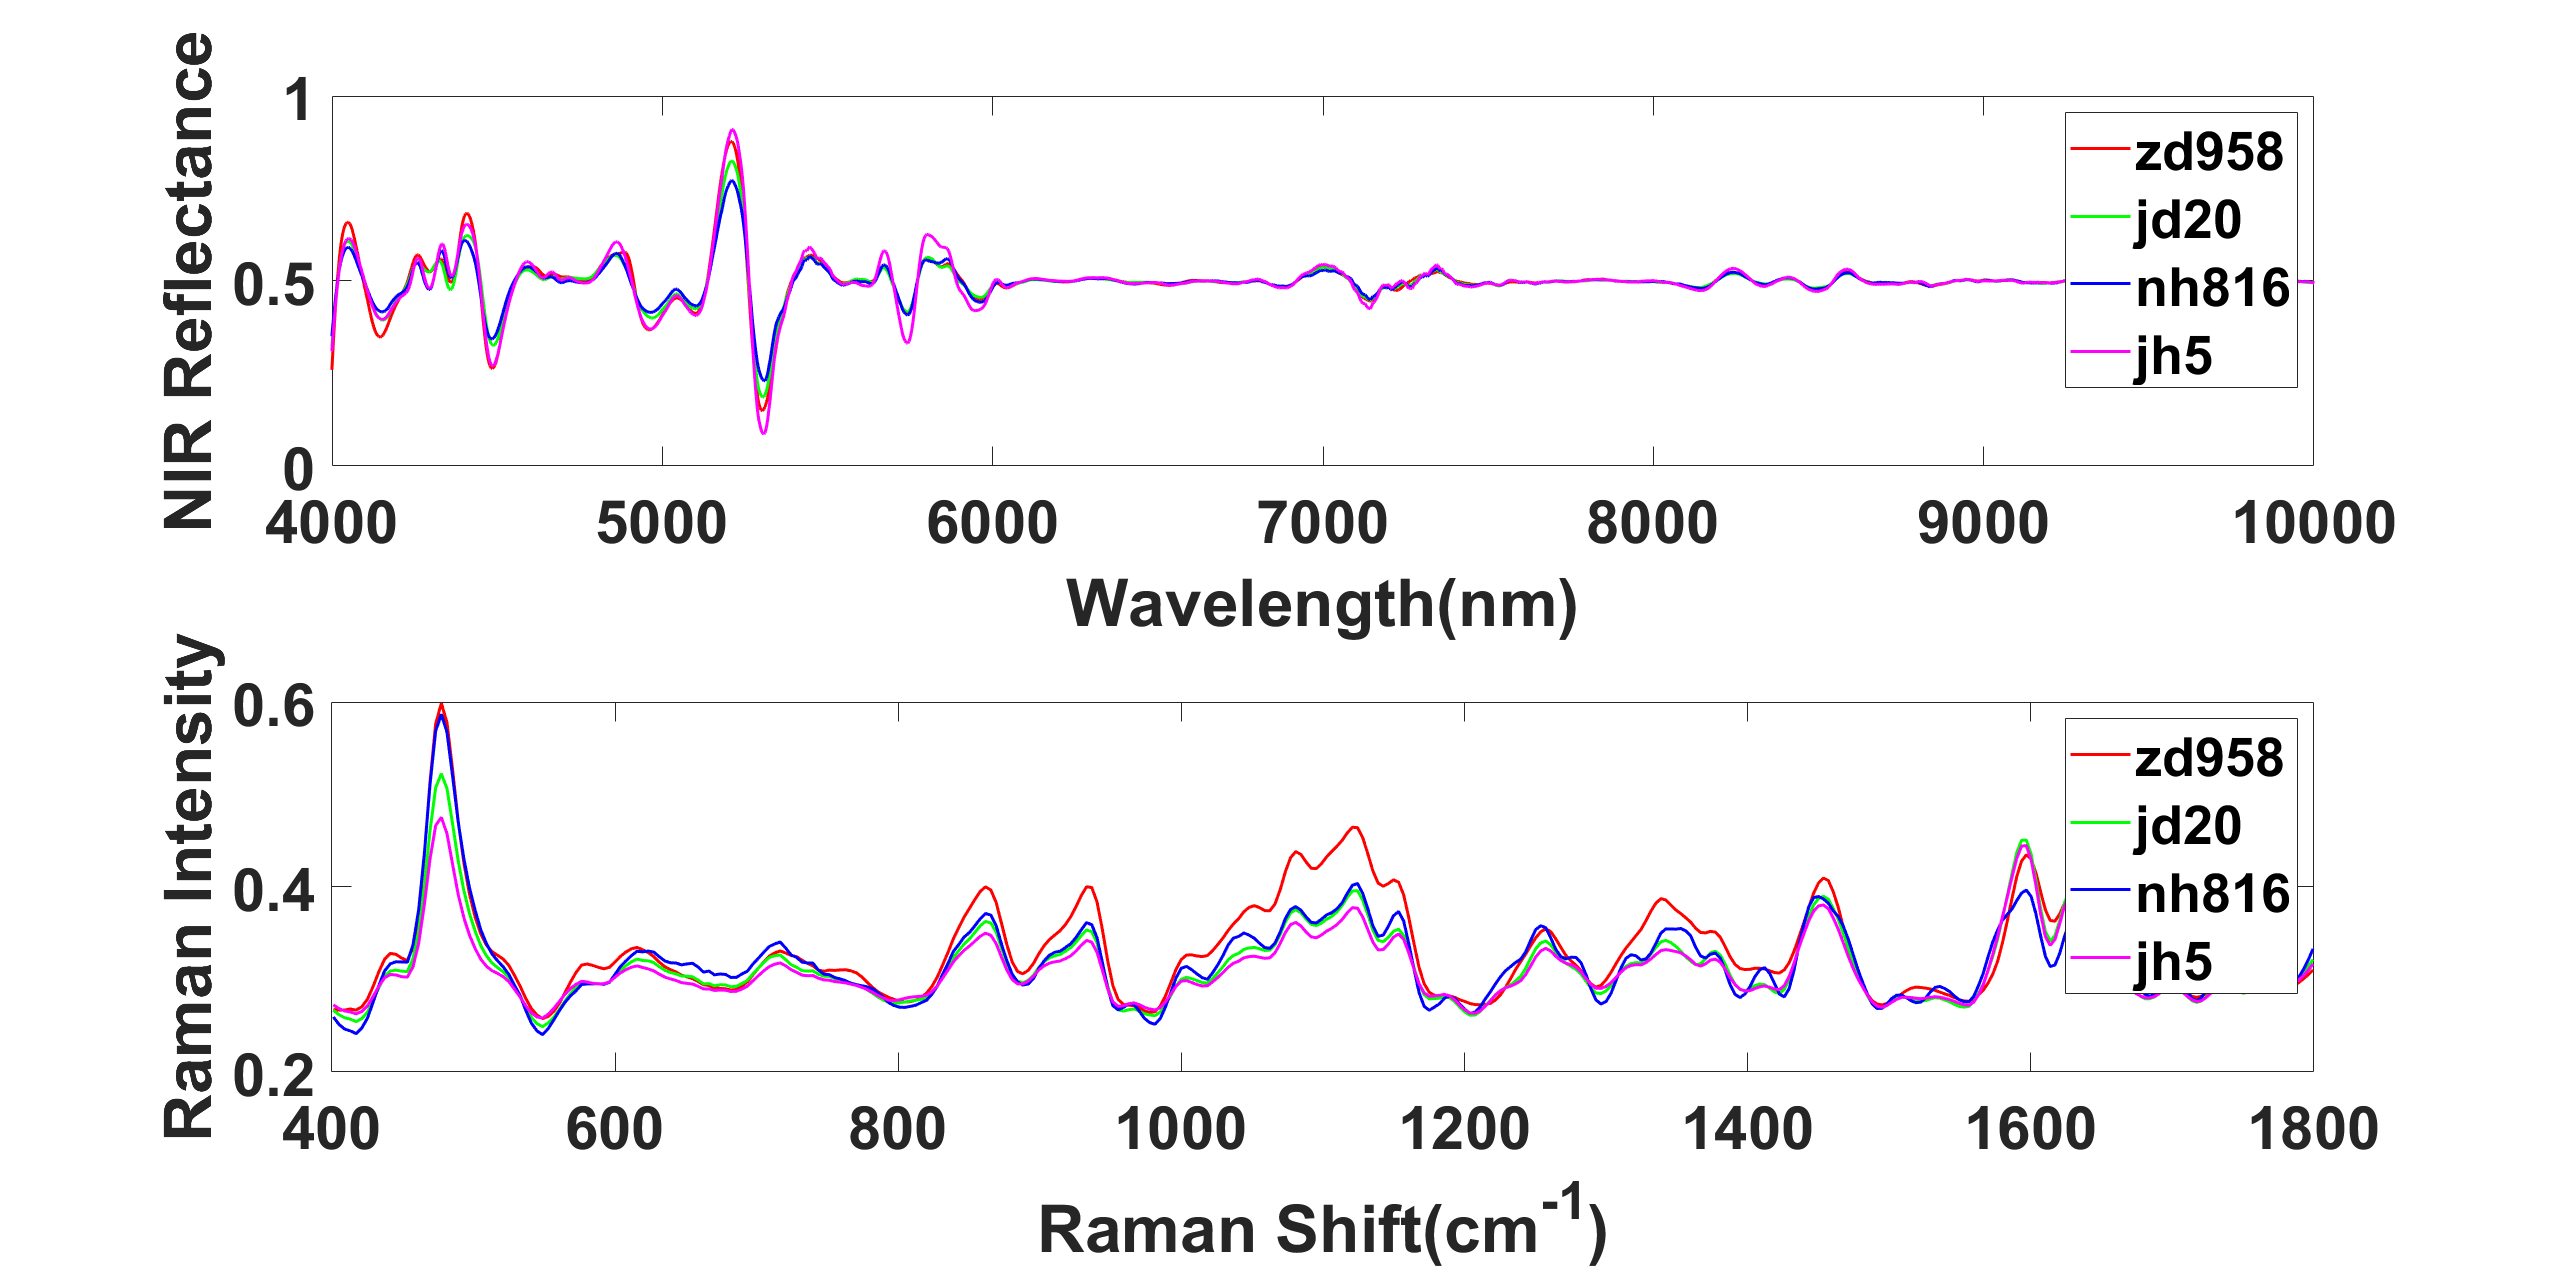

figure('Units','normalized','Position',[0, 0, 1, 0.8]);

subplot(2,1,1);
seed_varieties = ["zd958", "jd20", "nh816", "jh5"];
colors = ['r', 'g', 'b', 'm'];
for k = 1:length(seed_varieties)
    plot(wavenumber, avedata_variety_ftnir(k, :), "Color", colors(k), "LineWidth", 1.5);
    hold on;
end

% for k = 1:length(seed_varieties)
%     plot(raman_wavelengths, avedata_variety(k, :), "Color", colors(k), "LineWidth", 1.5);
%     hold on;
% end

xlim([4000, 10000])
xlabel('Wavelength(nm)')
ylabel('NIR Reflectance')
legend(seed_varieties) 
set(gca,'fontsize',30, 'FontWeight','bold');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(2,1,2);

seed_varieties = ["zd958", "jd20", "nh816", "jh5"];
colors = ['r', 'g', 'b', 'm'];

for k = 1:length(seed_varieties)
    plot(effshift, avedata_variety(k, :), "Color", colors(k), "LineWidth", 1.5);
    hold on;
end

xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
legend(seed_varieties) 
set(gca,'fontsize',30, 'FontWeight','bold');